# [IPSA] - Automatique - Projet drone

# Fichier de paramètres - controller

Auteur : Adrien Jacob 

______________________________________________________________________________________________________________

**P.S. **Cette fonctionnalité est encore en phase de test, si vous rencontrez des problème de configuration avec votre manette, n'hésitez pas à revenir vers moi.

______________________________________________________________________________________________________________

**1. Type de controller utilisé**

Visiblement les controleurs dans le commerce ne sont pas mappé de la même façon (notamment au niveau du Joystick droit / gachettes)

Deux configurations testés :

- manette type XBOX 

- manette type PS5 

Réglez le "manual switch en conséquence"

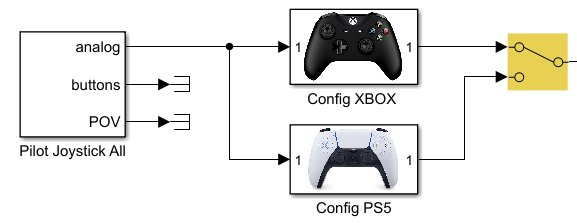

______________________________________________________________________________________________________________

**2. Configuration pour contrôle manuel**

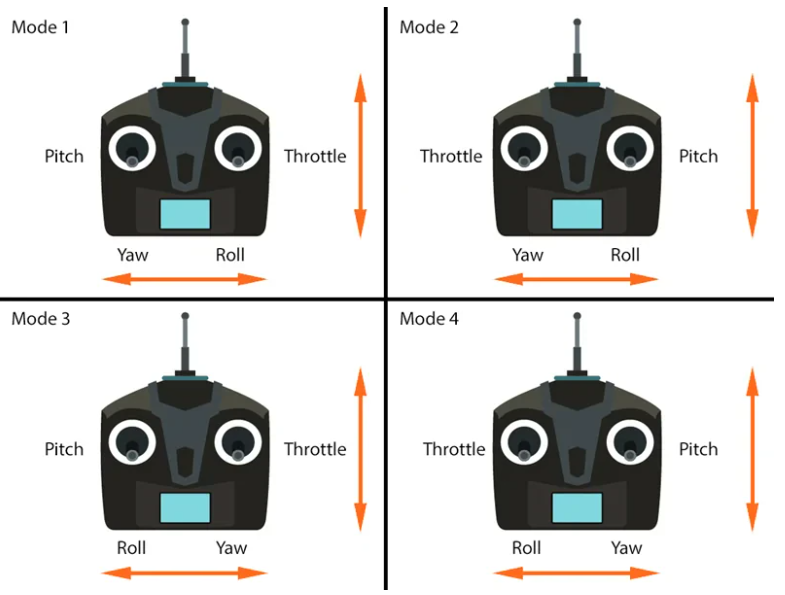

Le mode 2 est la config la plus utilisée dans le monde (question de préférence)

- `control_mode` selectionne le mode de controle ci-dessus.

- `ratio_control` modifie les gains sur les Joysticks et modifie la maniabilité, manette en main.

- `rate_limits` borne la variation de commande, notamment lors d'un engagement fort du Joystick.

% choix du mode de control :
control_mode = 3;

% Gains sur les commandes (Trust / C_roll / C_pitch / C_Yaw) :
ratio_control = [1 0.25 0.25 0.25]';

% Rate limiter si trop dynamique :
rate_limits = [inf inf inf inf]';

______________________________________________________________________________________________________________

**3. Calcul des gains sur les Joysticks en fonction des paramètres du drone**

switch control_mode
    case 1; c_mode = [3 4 2 1]; g_mode = [-1 -1 -1 -1]';
    case 2; c_mode = [2 4 3 1]; g_mode = [-1 -1 -1 -1]';
    case 3; c_mode = [3 1 2 4]; g_mode = [-1 1 -1 1]';
    case 4; c_mode = [2 1 3 4]; g_mode = [-1 1 -1 1]';
end

% Definition des gains en fonction du drone :
C_phi_max =     params.L * params.kt * params.Wmot2_sat(2); % [N.m]
C_theta_max =   params.L * params.kt * params.Wmot2_sat(2); % [N.m]
C_psi_max =     params.kc * params.Wmot2_sat(2);            % [N.m]

joystick_gains = ratio_control .* g_mode ...
    .* [params.Moteur_T_max*4 - params.Moteur_T_hover; ...
        C_phi_max; ... 
        C_theta_max; ...
        C_psi_max];


______________________________________________________________________________________________________________

**4. Structure "controller" et affichage**

% structure de paramètres utiles :
controller = struct(...
    'control_mode', control_mode, ...
    'c_mode', c_mode, ...
    'ratio_control', ratio_control, ...
    'rate_limits', rate_limits, ...
    'joystick_gains', joystick_gains ...
);

% nettoyage du workspace :
clear control_mode c_mode g_mode ...
      ratio_control rate_limits joystick_gains ...
      C_phi_max C_theta_max C_psi_max;

% Affichage
disp('=== Paramètres du controller ===');

=== Paramètres du controller ===


disp(' ');

disp(controller);

      control_mode: 3
            c_mode: [3 1 2 4]
     ratio_control: [4×1 double]
       rate_limits: [4×1 double]
    joystick_gains: [4×1 double]

